# Task 1

clear
clc
disp("Task 1")

Task 1


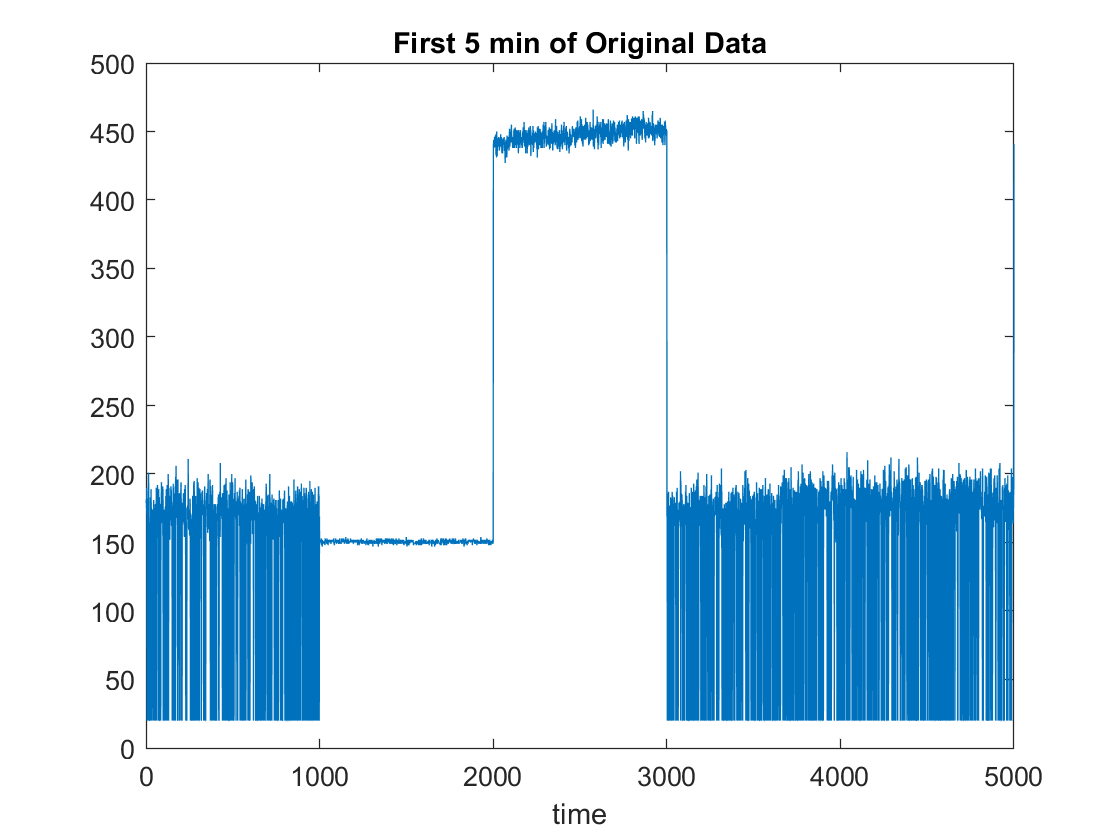

load("Data.mat") % 10 min data
fs=16.6667; % Sampling Frequency
ts=0.06; % Time period

plot(SensorData(1:5000,1)); % Plotting Original data
title("First 5 min of Original Data")
xlabel("time")


%1 min no motion noise shown on graph
%2 min object at 150mm from sensor
%3min student at 450mm from sensor
%4-5 min noise

% fluctutations in data in 2-3 min due to breathing movement of student
disp("..............................................")% Task 1 ended

..............................................


# Task 2

## Second Minute

disp("Task 2")

Task 2


% Data for Second minute
two_min_data=SensorData(1001:2000,1);

% 2nd min average taken to remove irregularites
mean_of_2nd_min=mean(two_min_data)

mean_of_2nd_min = 150.5130

## Third minute

% Data for Third minute
three_min_data=SensorData(2001:3000,1); 

% Time interval for 3rd min
time_interval = linspace(1,1000,1000);
time_interval=time_interval'; % to flip 1x1000 to 1000x1 to match dimensions

% Using polynomial fit to smoothen the data for 3rd min
p=polyfit(time_interval,three_min_data,21);%polynomial fit applied to 3rd min

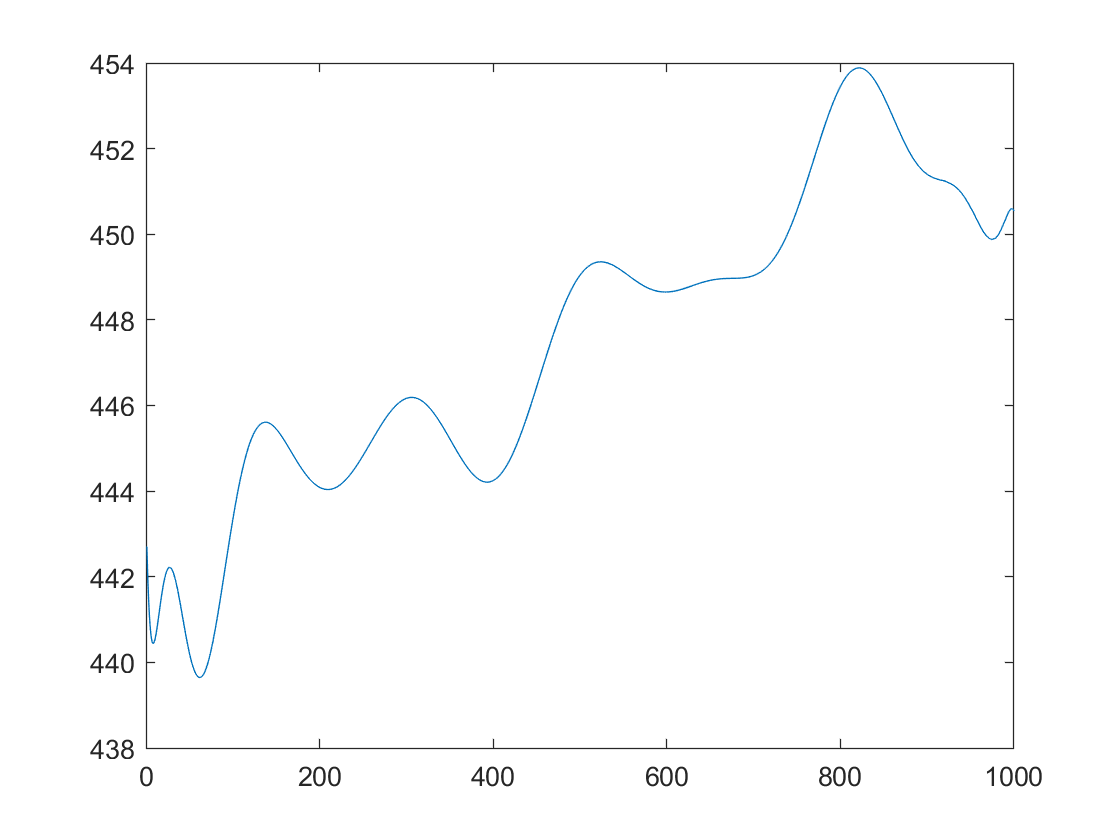

cleaned_data_of_3rd_min=polyval(p,time_interval); %data smoothened
plot(cleaned_data_of_3rd_min) 

title("Cleaned Data of 3rd minute")
%Finding number of peaks
no_of_peaks_in_3rd_min=findpeaks(cleaned_data_of_3rd_min);

%Finding number of peaks
no_of_breathes_in_3rd_min = length(no_of_peaks_in_3rd_min) % using peak finder function for breaths

no_of_breathes_in_3rd_min = 8


%% Checking bestfit line of plotfit is moving through data
%plot(t2,new);hold on
%plot(t2,three_min,'ro');hold off

## Storing clean data

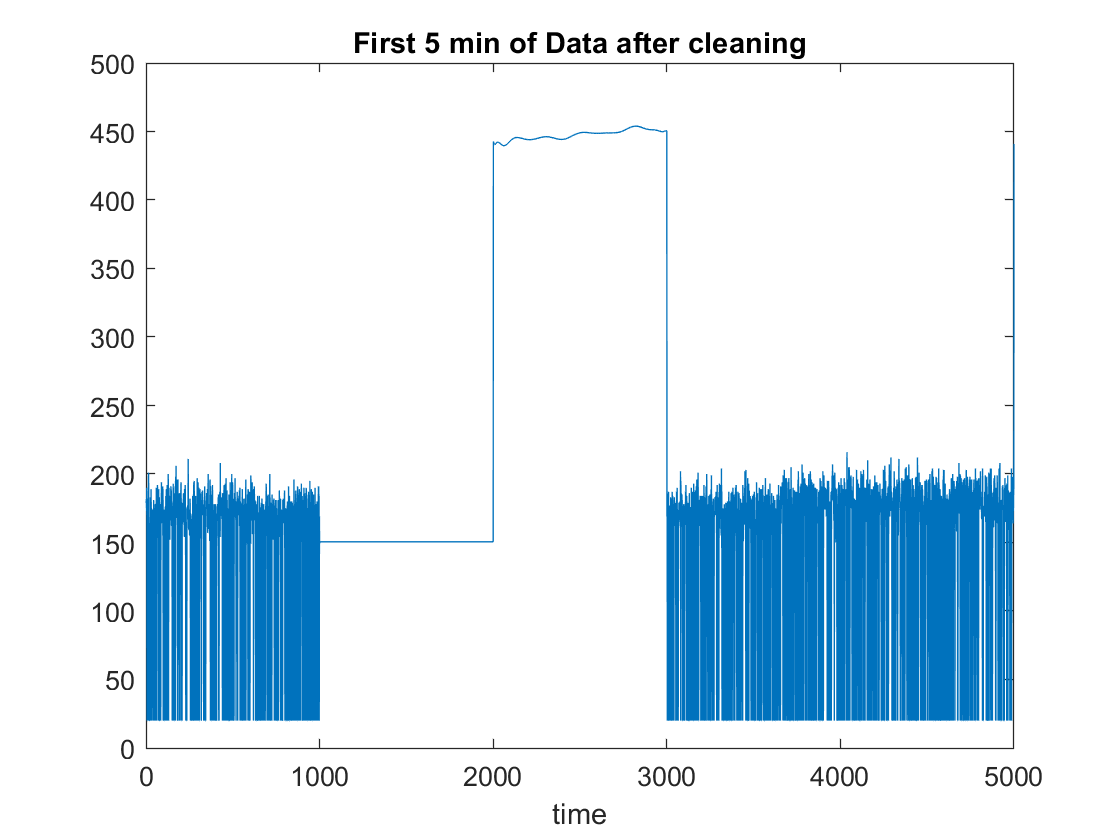

cleaned_data_after_T2 = SensorData;
cleaned_data_after_T2(1001:2000,1) = mean_of_2nd_min; % Storing cleaned data for 2nd min
cleaned_data_after_T2(2001:3000,1) = cleaned_data_of_3rd_min; % Storing cleaned data for 3rd min

% Plot full cleaned data for first 5mins
plot(cleaned_data_after_T2(1:5000,1)); 
title("First 5 min of Data after cleaning")
xlabel("time")

disp("..............................................")% Task 2 ended

..............................................


# Task 3

## Separatly storing Data for 10 minutes 

disp("Task 3")

Task 3


one_min_data=cleaned_data_after_T2(1:1000,1);
two_min_data=cleaned_data_after_T2(1001:2000,1);
three_min_data=cleaned_data_after_T2(2001:3000,1);
four_min_data=cleaned_data_after_T2(3001:4000,1);
five_min_data=cleaned_data_after_T2(4001:5000,1);
six_min_data=cleaned_data_after_T2(5001:6000,1);
seven_min_data=cleaned_data_after_T2(6001:7000,1);
eight_min_data=cleaned_data_after_T2(7001:8000,1);
nine_min_data=cleaned_data_after_T2(8001:9000,1);
ten_min_data=cleaned_data_after_T2(9001:10000,1);

## Plotting Data to match missing Data

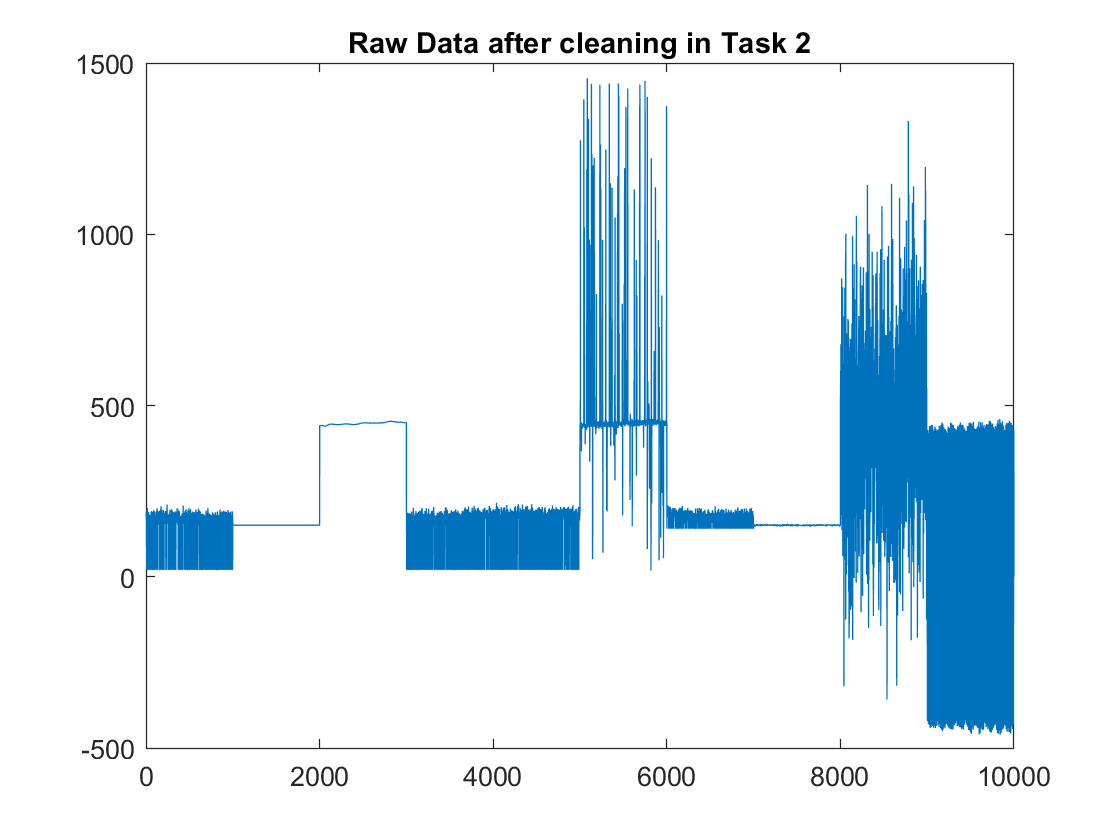

% Dispalying Raw Data after cleaning in Task 2
plot(cleaned_data_after_T2)
title("Raw Data after cleaning in Task 2")

##  Variance of First 5 minutes (known)

disp("Data is known for first 5 minutes:")

Data is known for first 5 minutes:


disp("--") % Space

--


disp("1st minute:")

1st minute:


one_min_variance=var(one_min_data)

one_min_variance = 4.5746e+03

disp("->There is no object present.")

->There is no object present.


disp("--") % Space

--


disp("2nd minute:")

2nd minute:


two_min_variance=var(two_min_data)

two_min_variance = 1.3665e-25

disp("->There is object present at some distant.")

->There is object present at some distant.


disp("--") % Space

--


disp("3rd minute:")

3rd minute:


three_min_variance=var(three_min_data)

three_min_variance = 12.3629

disp("->There a person is present.")

->There a person is present.


disp("--") % Space

--


disp("4th minute:")

4th minute:


four_min_variance=var(four_min_data)

four_min_variance = 4.8170e+03

disp("->There is no object present.")

->There is no object present.


disp("--") % Space

--


disp("5th minute:")

5th minute:


five_min_variance=var(five_min_data)

five_min_variance = 4.8233e+03

disp("->There is no object present.")

->There is no object present.


disp("--") % Space

--


## Variance of Last 5 minutes (unknown)

disp("Data is unknown for last 5 minutes")

Data is unknown for last 5 minutes


disp("--") % Space

--


disp("6th minute:")

6th minute:


six_min_uncleaned_variance=var(six_min_data)

six_min_uncleaned_variance = 2.8512e+04

disp("->Data is unknown in Sixth minute because data is too corupted.")

->Data is unknown in Sixth minute because data is too corupted.


disp("--") % Space

--


disp("7th minute:")

7th minute:


seven_min_uncleaned_variance=var(seven_min_data)

seven_min_uncleaned_variance = 355.2163

disp("->Data is unknown in Seveth minute because data is too corupted.")

->Data is unknown in Seveth minute because data is too corupted.


disp("--") % Space

--


disp("8th minute:")

8th minute:


eight_min_uncleaned_variance=var(eight_min_data)

eight_min_uncleaned_variance = 2.1202

disp("->In Eighth minute there is object present at some distant because the variance is similar to variance of 2nd minute.")

->In Eighth minute there is object present at some distant because the variance is similar to variance of 2nd minute.


disp("--") % Space

--


disp("9th minute:")

9th minute:


nine_min_uncleaned_variance=var(nine_min_data)

nine_min_uncleaned_variance = 6.1869e+04

disp("->Data is unknown in Nineth minute because data is too corupted.")

->Data is unknown in Nineth minute because data is too corupted.


disp("--") % Space

--


disp("10th minute:")

10th minute:


ten_min_uncleaned_variance=var(ten_min_data)

ten_min_uncleaned_variance = 1.0018e+05

disp("->Data is unknown in Tenth minute because data is too corupted.")

->Data is unknown in Tenth minute because data is too corupted.


disp("--") % Space

--


## Result of using Variance

disp("Only eighth minute can be identified using Variance.")

Only eighth minute can be identified using Variance.


disp("..............................................")% Task 3 ended

..............................................


# Task 4

disp("Task 4")

Task 4


recovered_data_after_T4 = cleaned_data_after_T2; % First 5 minutes are known

## Recovering data for 6th minute

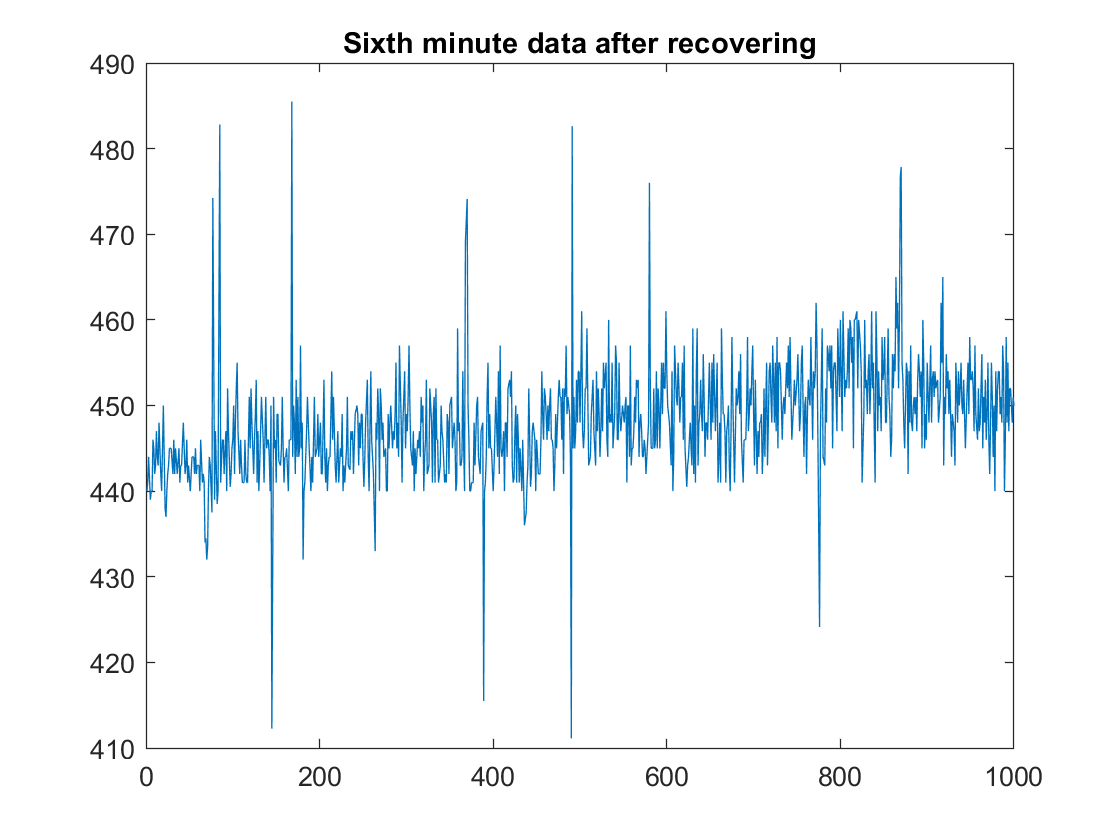

cleaned_6 = false; % Flag
six_recovered = six_min_data; %Initialising
while cleaned_6 == false % Repeat until data is cleaned to set limit
    cleaned_6 = true;
    compare_6_min_greater = mean(six_recovered) + 40; % Setting threshold to compare
    compare_6_min_lesser = mean(six_recovered) - 40; % Setting threshold to compare
    six_correct = six_recovered; 
    for i = 1 : 1000
        if six_recovered(i) > compare_6_min_greater % Comparing with threshold
            average = (six_recovered(i-1) + six_recovered(i+1))/2; % Calculating average
            six_correct(i) = average; % Storing calculated value
            cleaned_6 = false; 
        end
        if six_recovered(i) < compare_6_min_lesser % Comparing with threshold
            average = (six_recovered(i-1) + six_recovered(i+1))/2; % Calculating average
            six_correct(i) = average; % Storing calculated value
            cleaned_6 = false;
        end
    end
    six_recovered = six_correct; % Storing cleaned data so far
end
plot(six_recovered)
title("Sixth minute data after recovering")

% Saving recovered data
recovered_data_after_T4(5001:6000,1) = six_recovered;

## Recovering data for 7th minute

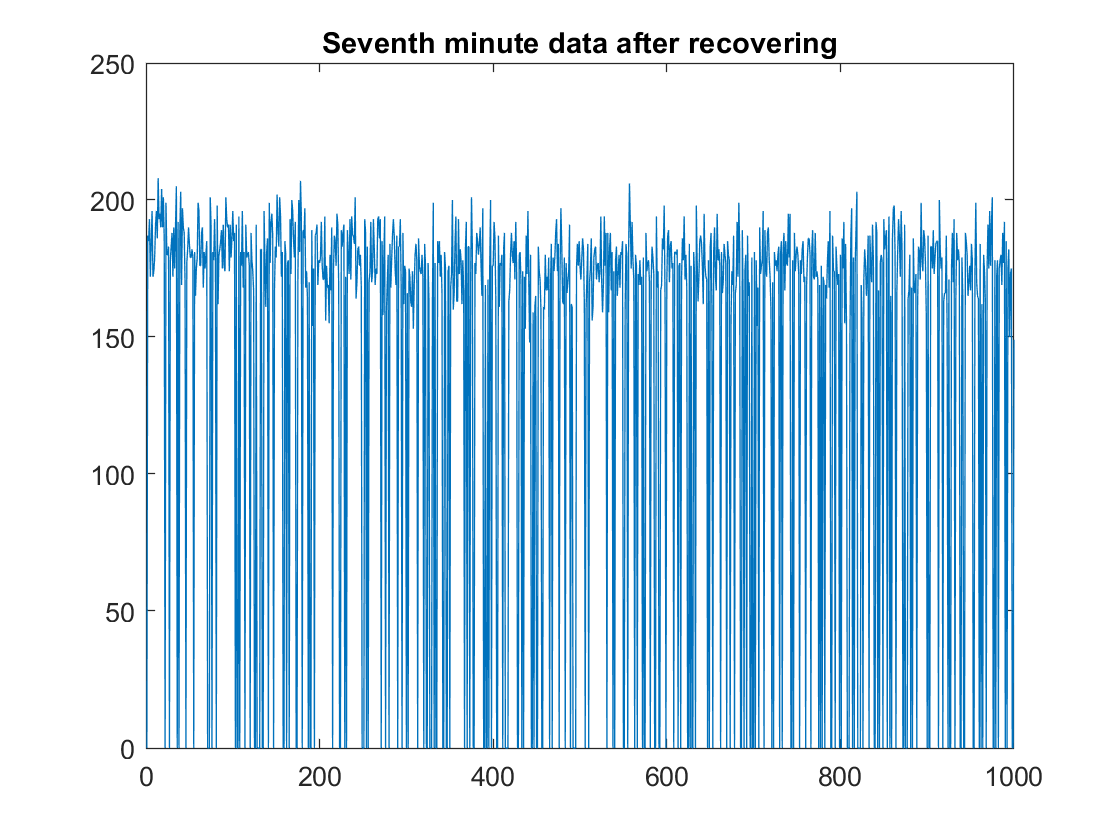

seven_recovered = seven_min_data; % Initialising
for i = 1 : 1000
    if seven_recovered(i) == 140
        seven_recovered(i) = 0;
    end
end
% Plotting cleaned 7th minute
plot(seven_recovered)
title("Seventh minute data after recovering")

% Saving recovered data
recovered_data_after_T4(6001:7000,1) = seven_recovered;

## Recovering data for 8th minute

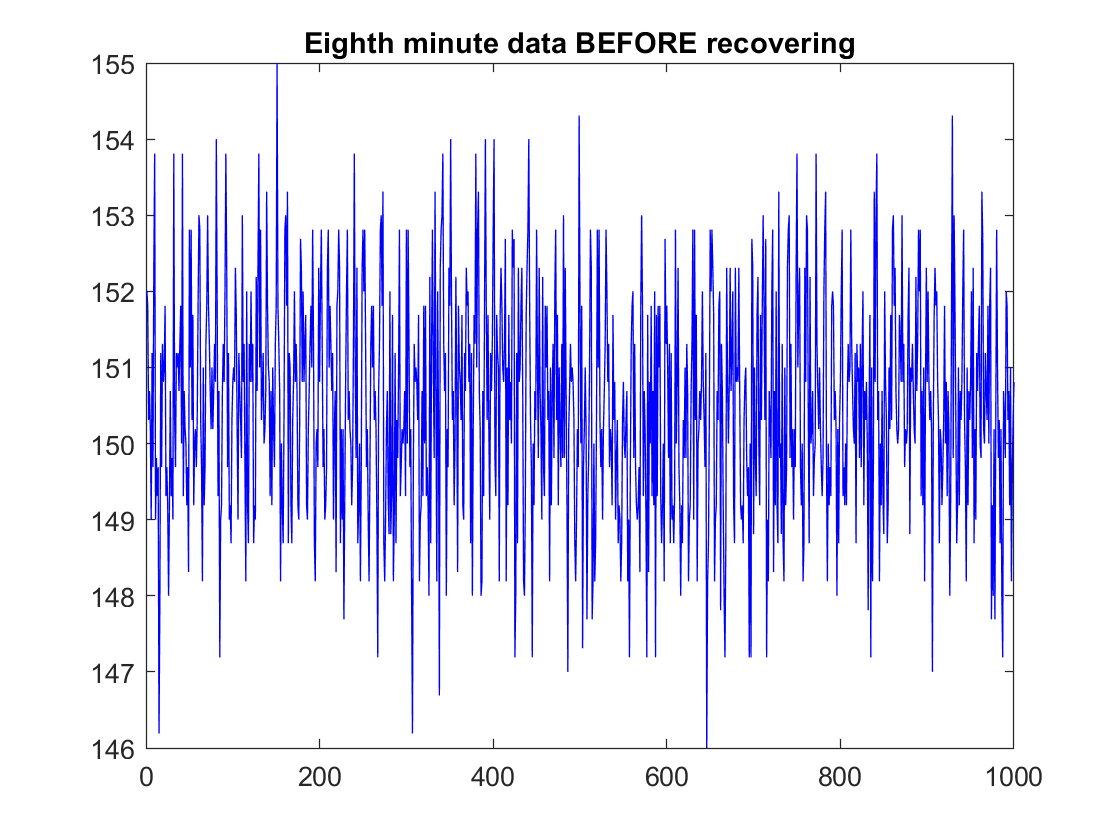

% Making Custom low pass filter
CUSTOM_low_pass_FILTER_8_min=designfilt('lowpassfir','FilterOrder',1,'CutoffFrequency',1,'SampleRate',fs);
% Applying Custom low pass filter
eight_recovered=filter(CUSTOM_low_pass_FILTER_8_min,eight_min_data);
% Plotting cleaned 8th minute
plot(eight_min_data,'b')
title("Eighth minute data BEFORE recovering")

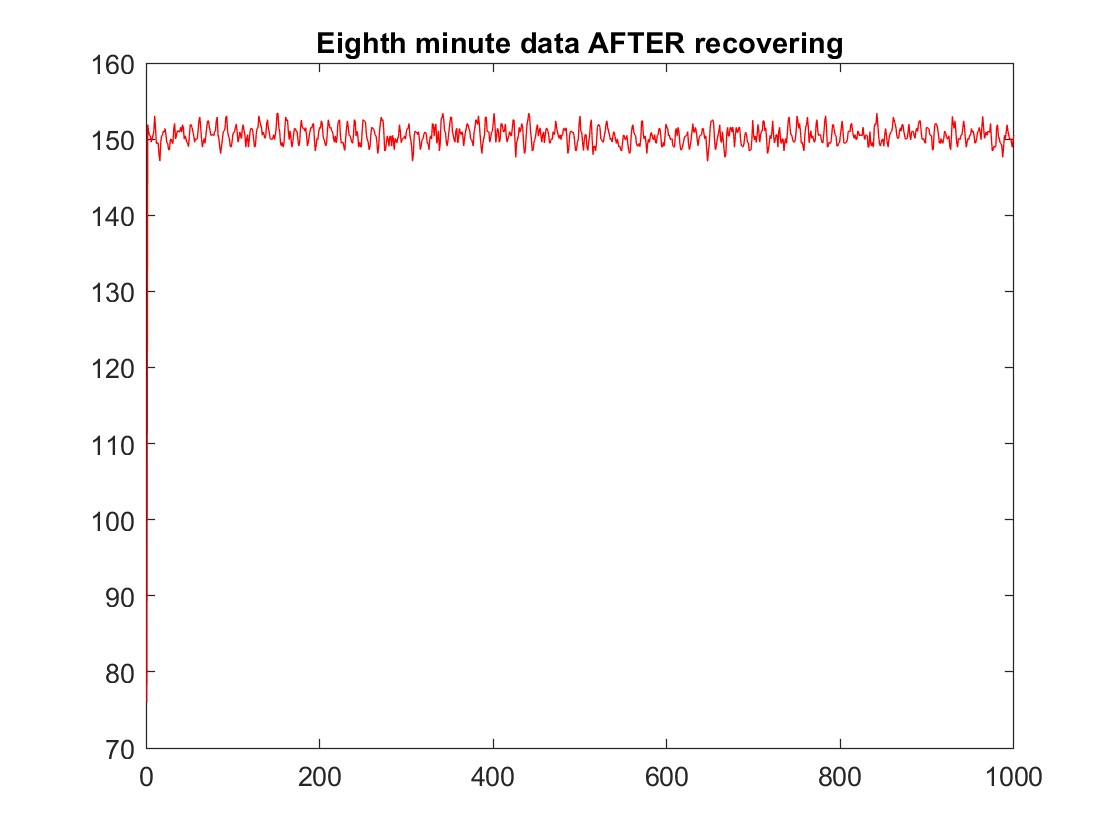

plot(eight_recovered,'r')
title("Eighth minute data AFTER recovering")

% Saving recovered data
recovered_data_after_T4(7001:8000,1) = eight_recovered;

## Recovering data for 9th minute

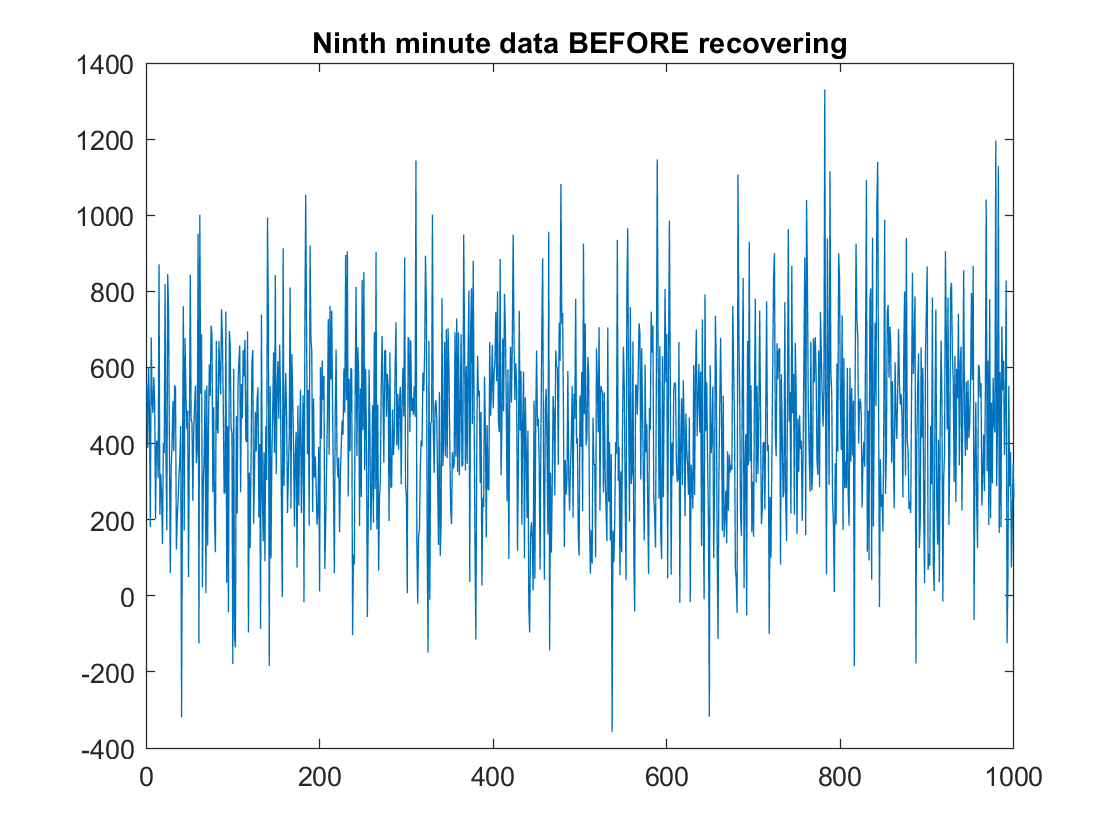

plot(nine_min_data);
title("Ninth minute data BEFORE recovering")

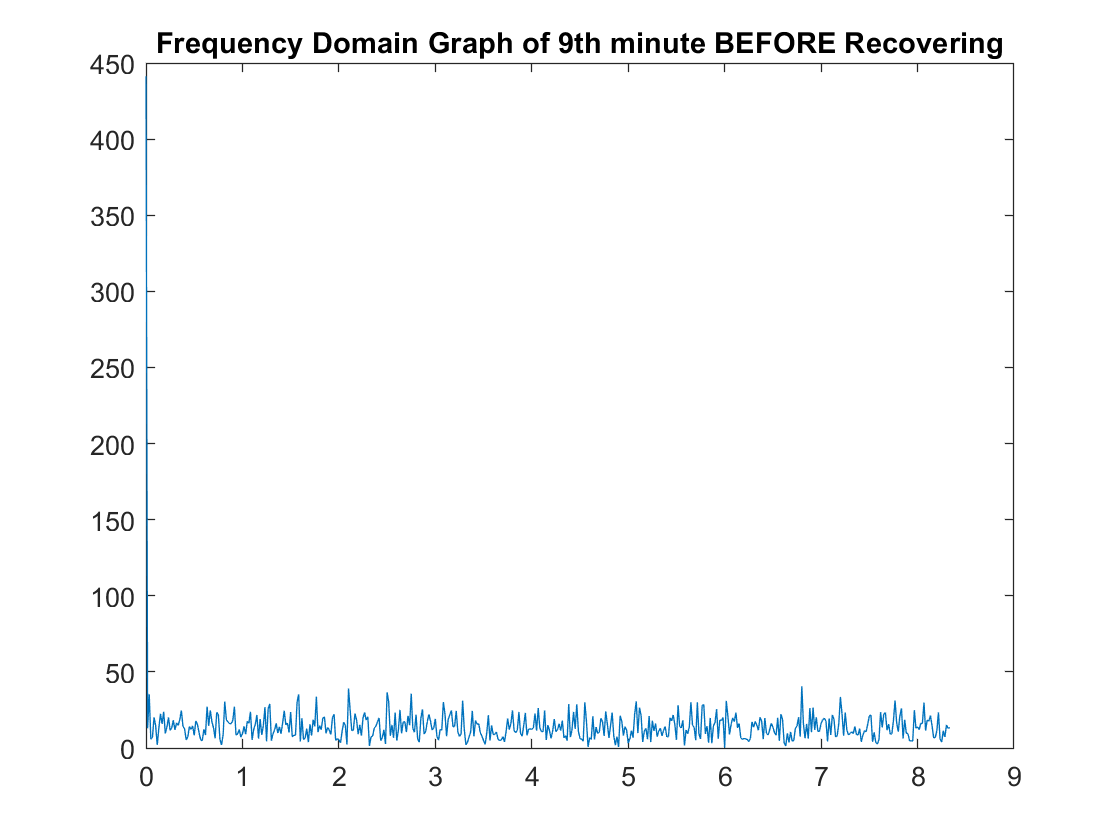

% Making Custom low pass filter
CUSTOM_low_pass_FILTER_9_min=designfilt('lowpassfir','FilterOrder',5,'CutoffFrequency',3,'SampleRate',fs);
% Cleaning 9th min
nine_cleaned=filter(CUSTOM_low_pass_FILTER_9_min,nine_min_data);

% frequency-domain of raw data 
[x_f, f] = frft(nine_min_data, fs);
plot(f, abs(x_f))
title("Frequency Domain Graph of 9th minute BEFORE Recovering")

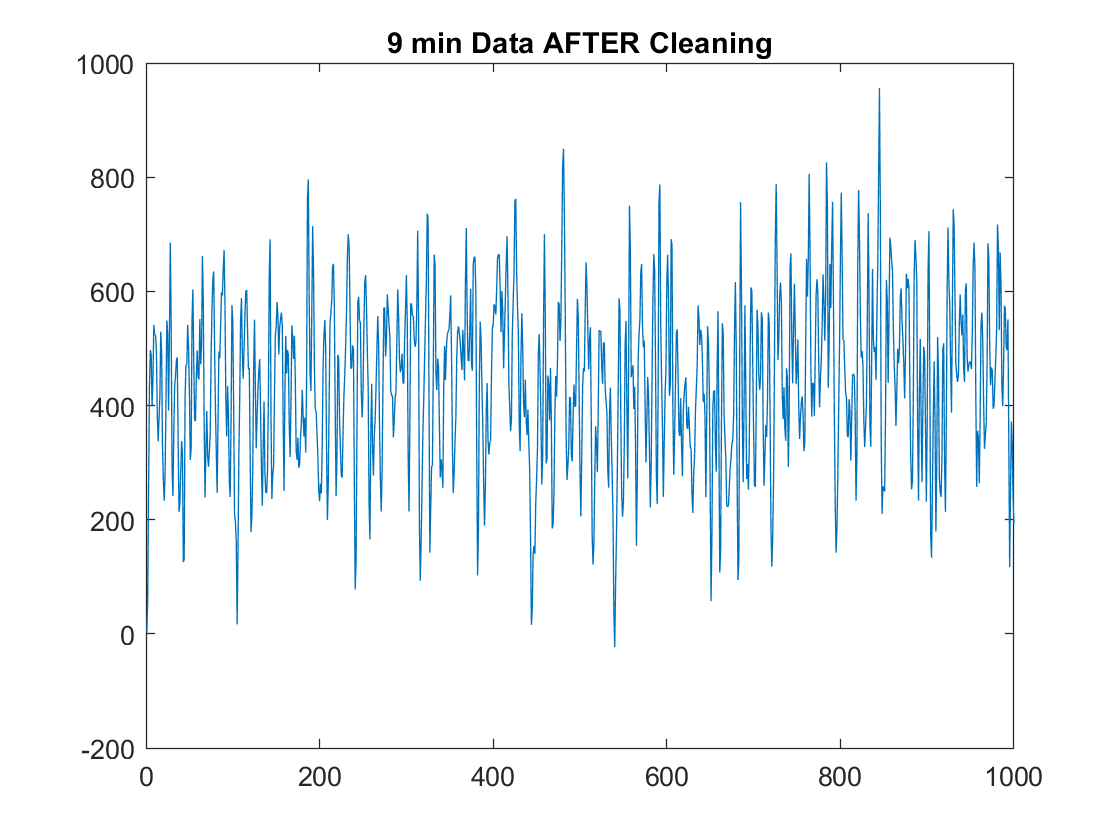

% Plotting cleaned 9 min data
plot(nine_cleaned);
title("9 min Data AFTER Cleaning")

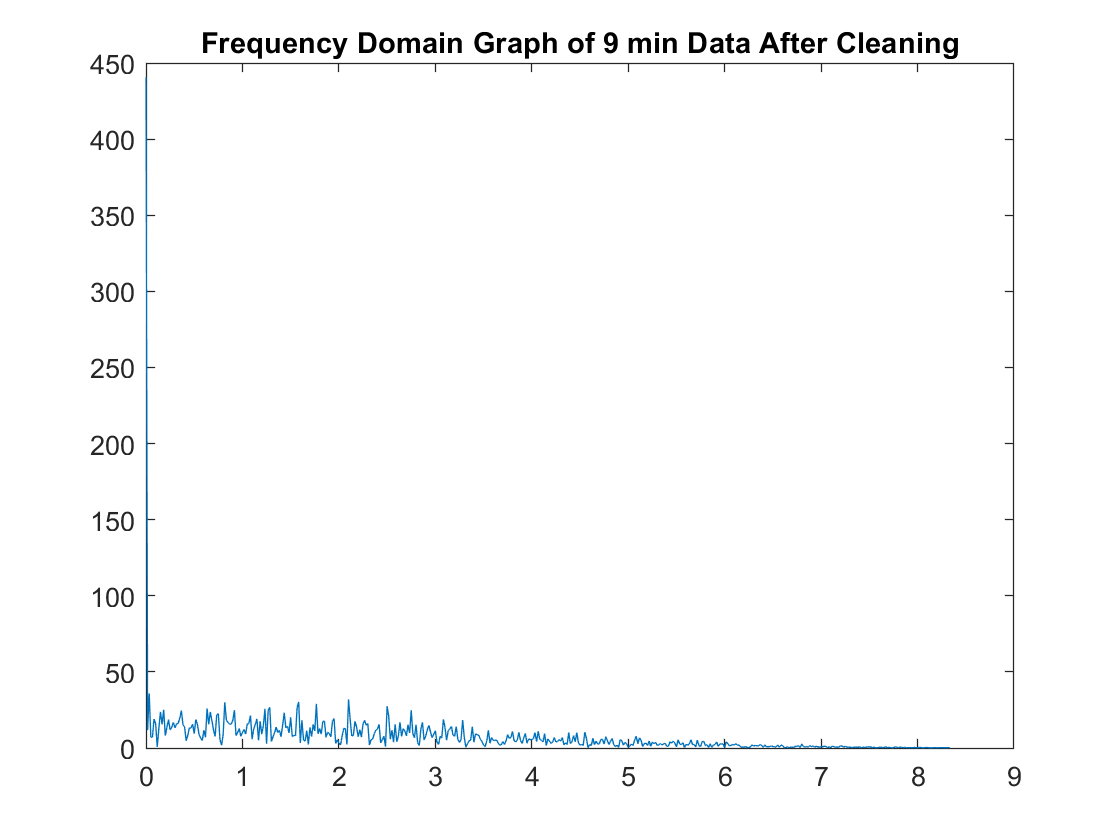


% frequency-domain of cleaned 9 min data
[x_f, f] = frft(nine_cleaned, fs);
plot(f, abs(x_f))
title("Frequency Domain Graph of 9 min Data After Cleaning")


% Using poltfit function  
p=polyfit(time_interval,nine_cleaned,21); % 21 because edge of discortion

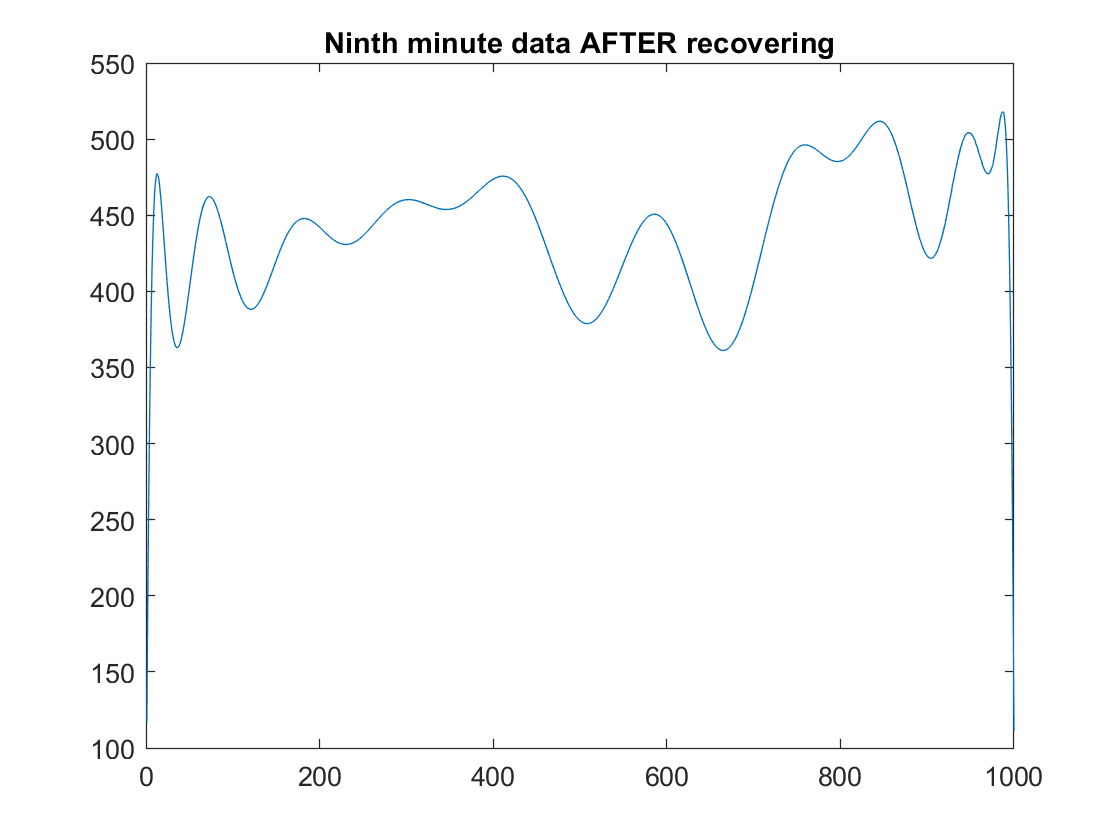

nine_recovered = polyval(p,time_interval);  % recovered data

% Plotting cleaned 9th minute
plot(nine_recovered);
title("Ninth minute data AFTER recovering")


% Saving recovered data
recovered_data_after_T4(8001:9000,1) = nine_recovered;

## Recovering data for 10th minute

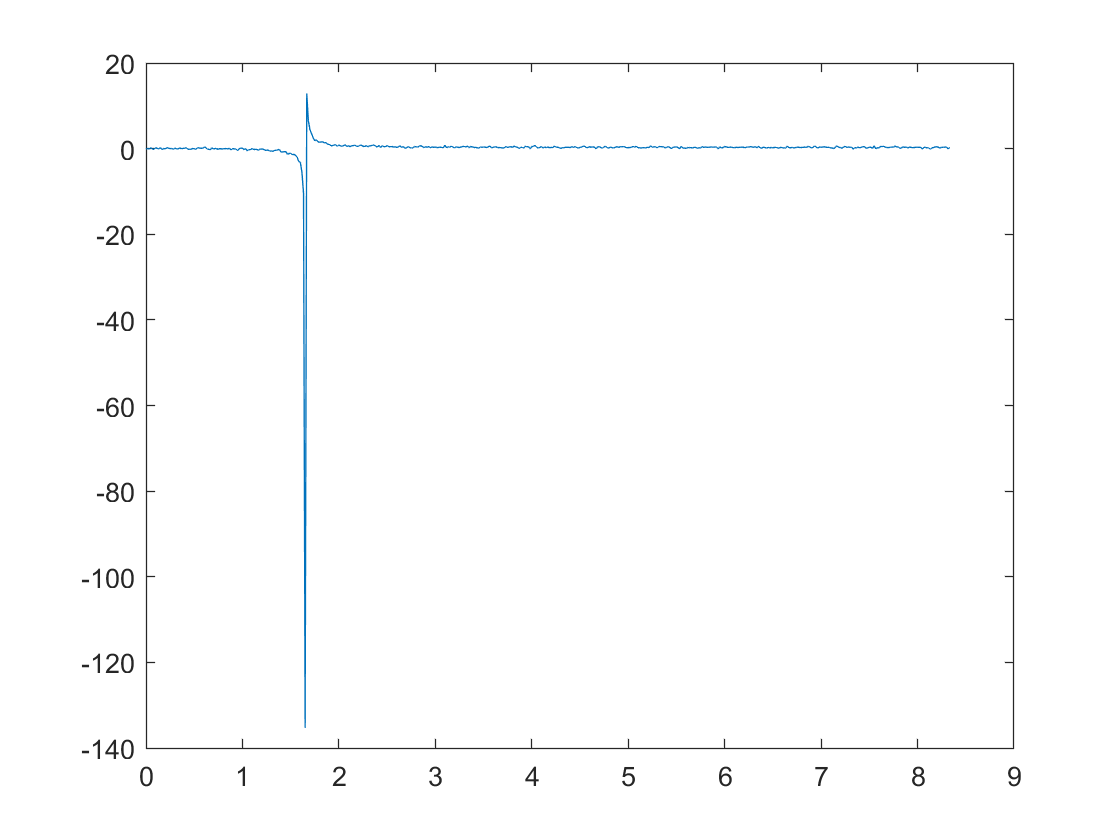

% frequency-domain
[x_f, f] = frft(ten_min_data, fs);
plot(f, x_f)

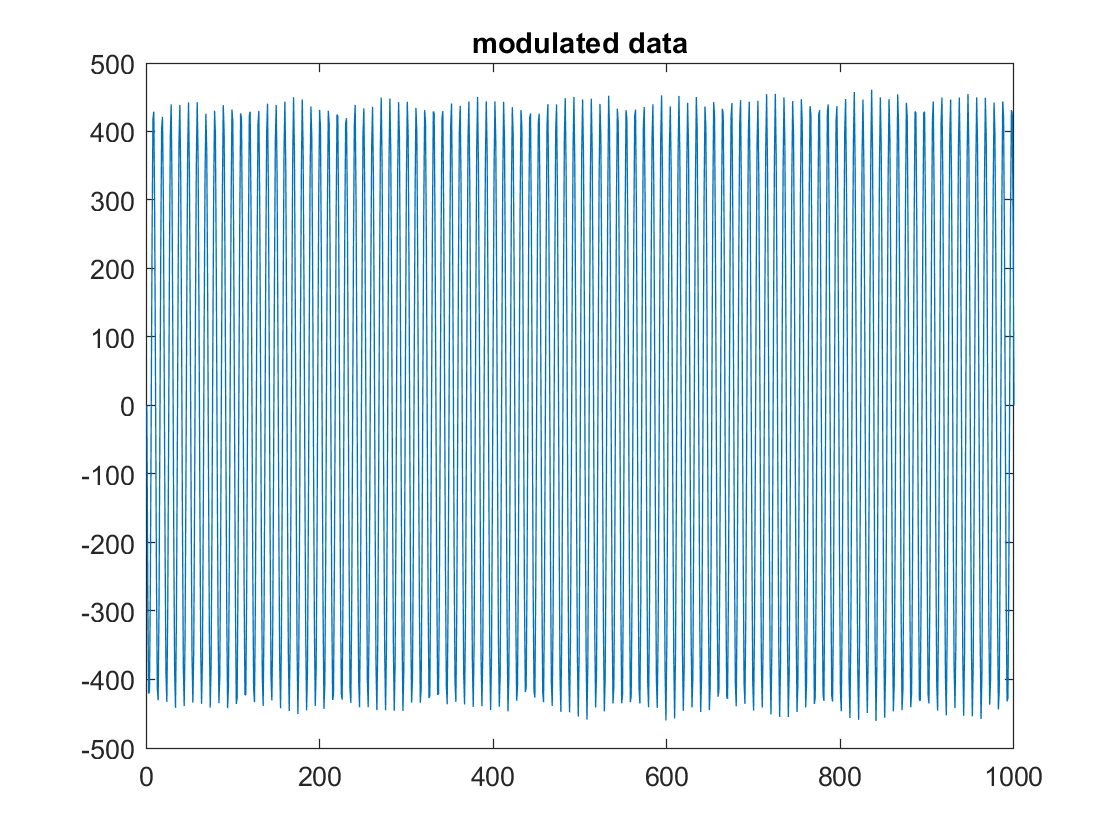


plot(ten_min_data);
title('modulated data')

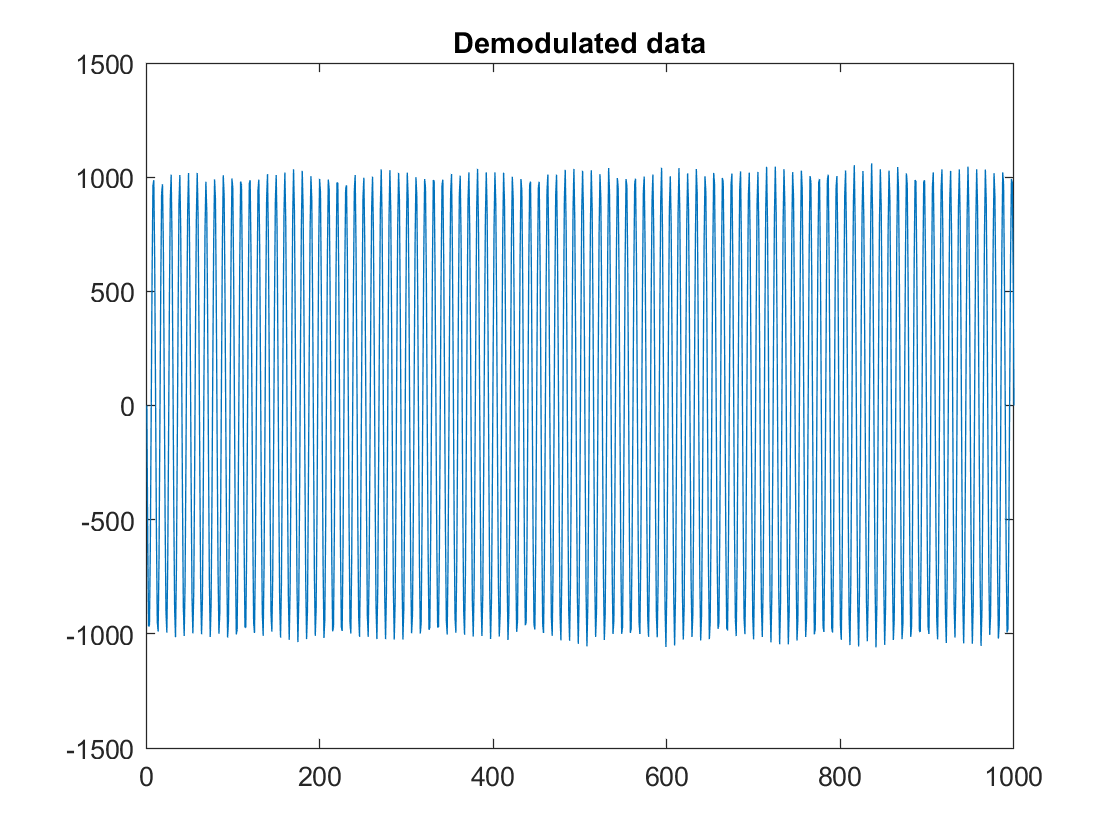


% Calculating Amplitude
a=1; %% largest element in corrupted data
% Frequency of cosine
f=15;

% Calculating Cosine Wave
cosine_wave=2.3*cos(2*pi*f*time_interval); % cosine wave
% Demodulation
demodulation_of_ten_min = cosine_wave.*ten_min_data; % multiplication

plot(demodulation_of_ten_min);
title('Demodulated data')

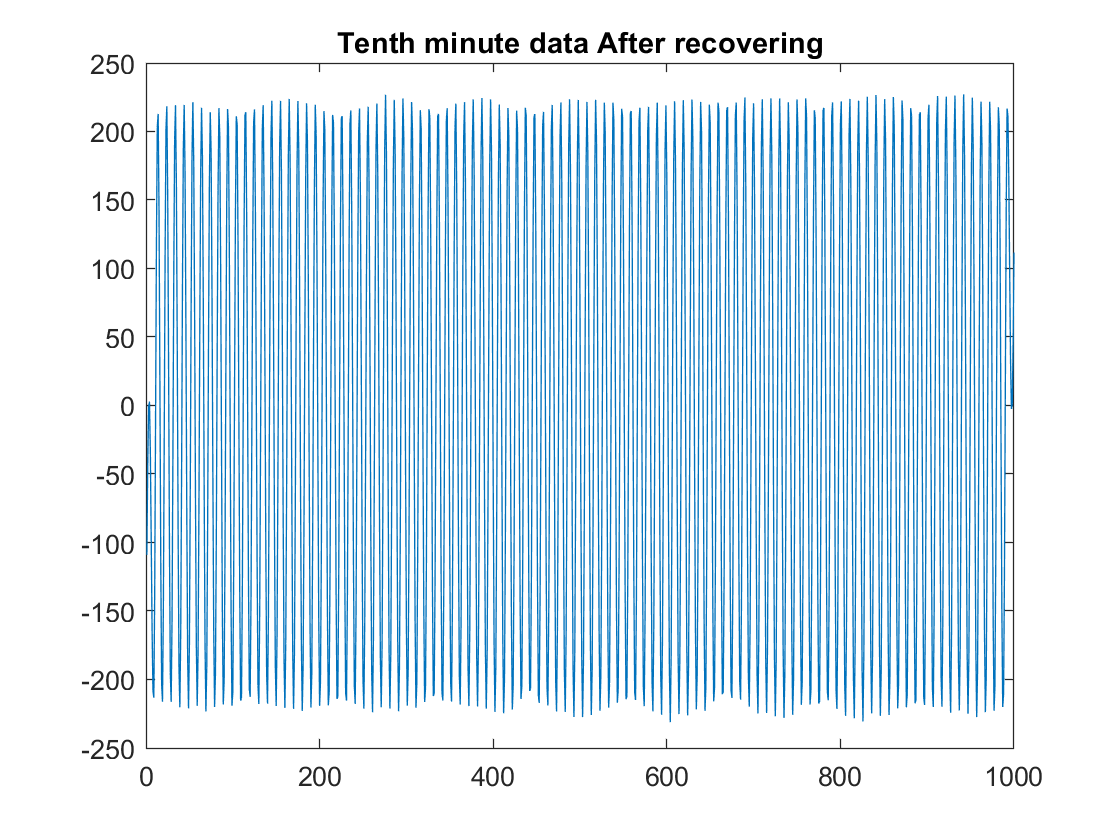


N = 15; % Minimum value of N required  % filter length
b = 1/N .*ones(1, N);
% Cleaning & saving data at same time
ten_recovered = conv(demodulation_of_ten_min, b, 'same');

plot(ten_recovered);
title("Tenth minute data After recovering")

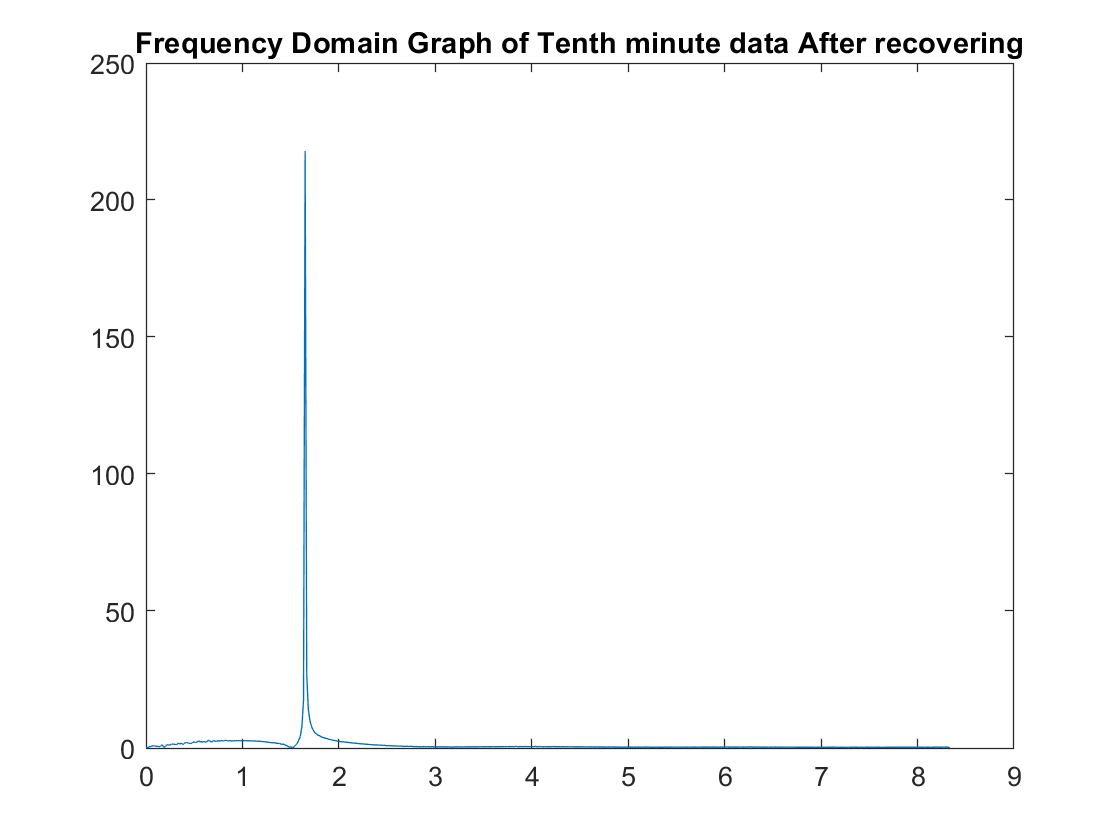


[x_f, f] = frft(ten_recovered, fs);
plot(f, abs(x_f));
title("Frequency Domain Graph of Tenth minute data After recovering")


% Saving recovered data
recovered_data_after_T4(9001:10000,1) = abs(ten_recovered);

#### Output of Recovered Data

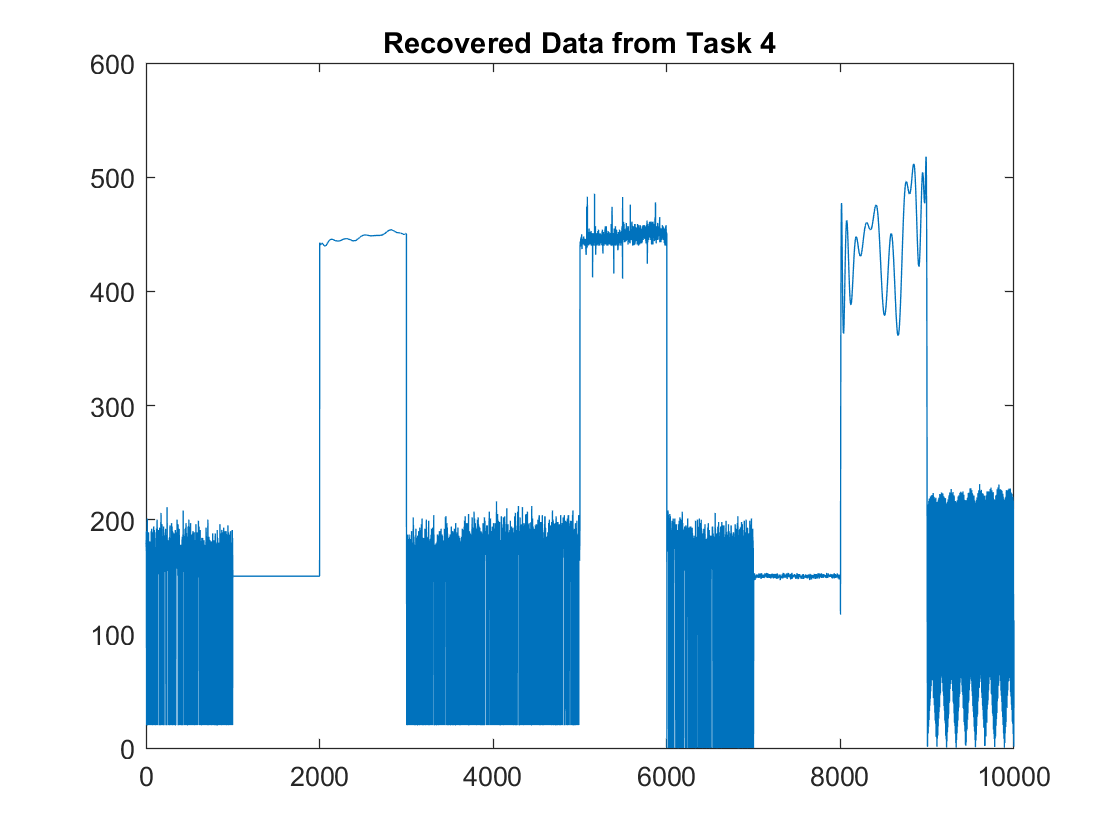

plot(recovered_data_after_T4)
title("Recovered Data from Task 4")

disp("..............................................")% Task 4 ended

..............................................


# Task 5

## Variance of First 5 minutes (known)

disp("Task 5")

Task 5


disp("Data is known for first 5 minutes:")

Data is known for first 5 minutes:


disp("--") % Space

--


% 1 min
disp("1st minute:")

1st minute:


disp("->There is no object present.")

->There is no object present.


one_min_variance

one_min_variance = 4.5746e+03

disp("--") % Space

--


% 2 min
disp("2nd minute:")

2nd minute:


disp("->There is object present at some distant.")

->There is object present at some distant.


two_min_variance

two_min_variance = 1.3665e-25

disp("--") % Space

--


% 3 min
disp("3rd minute:")

3rd minute:


disp("->There a person is present.")

->There a person is present.


three_min_variance

three_min_variance = 12.3629

disp("--") % Space

--


% 4 min
disp("4th minute:")

4th minute:


disp("->There is no object present.")

->There is no object present.


four_min_variance

four_min_variance = 4.8170e+03

disp("--") % Space

--


% 5 min
disp("5th minute:")

5th minute:


disp("->There is no object present.")

->There is no object present.


five_min_variance

five_min_variance = 4.8233e+03

disp("--") % Space

--


## Variance of Last 5 minutes (unknown)

disp("Data is unknown for last 5 minutes")

Data is unknown for last 5 minutes


disp("--") % Space

--


#### 6 minute

disp("6th minute:")

6th minute:


disp("->There a person is present because its variance is similar to that of 3rd minute.")

->There a person is present because its variance is similar to that of 3rd minute.


six_min_recovered_variance=var(six_recovered)

six_min_recovered_variance = 40.9374

disp("--") % Space

--


#### 7 minute

disp("7th minute:")

7th minute:


disp("->There is no object present because its variance is similar to that of 1st, 4th & 5th minutes.")

->There is no object present because its variance is similar to that of 1st, 4th & 5th minutes.


seven_min_recovered_variance=var(seven_recovered)

seven_min_recovered_variance = 5.7551e+03

disp("--") % Space

--


#### 8 minute

disp("8th minute:")

8th minute:


disp("->There is object present at some distant because the variance is similar to variance of 2nd minute.")

->There is object present at some distant because the variance is similar to variance of 2nd minute.


% In 8 minute the first two values are OUTLIERS
eight_min_recovered_variance=var(eight_recovered) % a few values do not follow the trend so variance calculated is affected

eight_min_recovered_variance = 6.8435

% 8 min Variance without outlier values
eight_recovered_without_OUTLIERS = recovered_data_after_T4(7003:8000,1); % Ignoring OUTLIER values
eight_recovered_without_OUTLIERS_variance = var(eight_recovered_without_OUTLIERS) % Variance without outliers

eight_recovered_without_OUTLIERS_variance = 1.2920

disp("--") % Space

--


#### 9 minute

disp("9th minute:")

9th minute:


disp("->no object present")

->Data is unknown in Nineth minute because data is too corupted.


disp("The graph matches that of a person presnet but our variance is different due to the limitation of our filter")
nine_min_recovered_variance=var(nine_recovered)

nine_min_recovered_variance = 1.9266e+03

disp("--") % Space

--


#### 10 minute

disp("10th minute:")

10th minute:


disp("->There is no object present because its variance is similar to that of 1st, 4th & 5th minutes.")

->There is no object present because its variance is similar to that of 1st, 4th & 5th minutes.


ten_min_recovered_variance=var(ten_recovered)

ten_min_recovered_variance = 2.4876e+04

disp("--") % Space

--


disp("..............................................")% Task 5 ended

..............................................


# Task 6

## Number of Breathes & Distance for Data labelled as Person

disp("Task 6")

Task 6


#### 6th minute Number of Breathes

disp("In 6th minute person is present")

In 6th minute person is present


% Using polynomial fit to smoothen the data for 6th min
p=polyfit(time_interval,six_recovered,23);%polynomial fit applied to 6th min

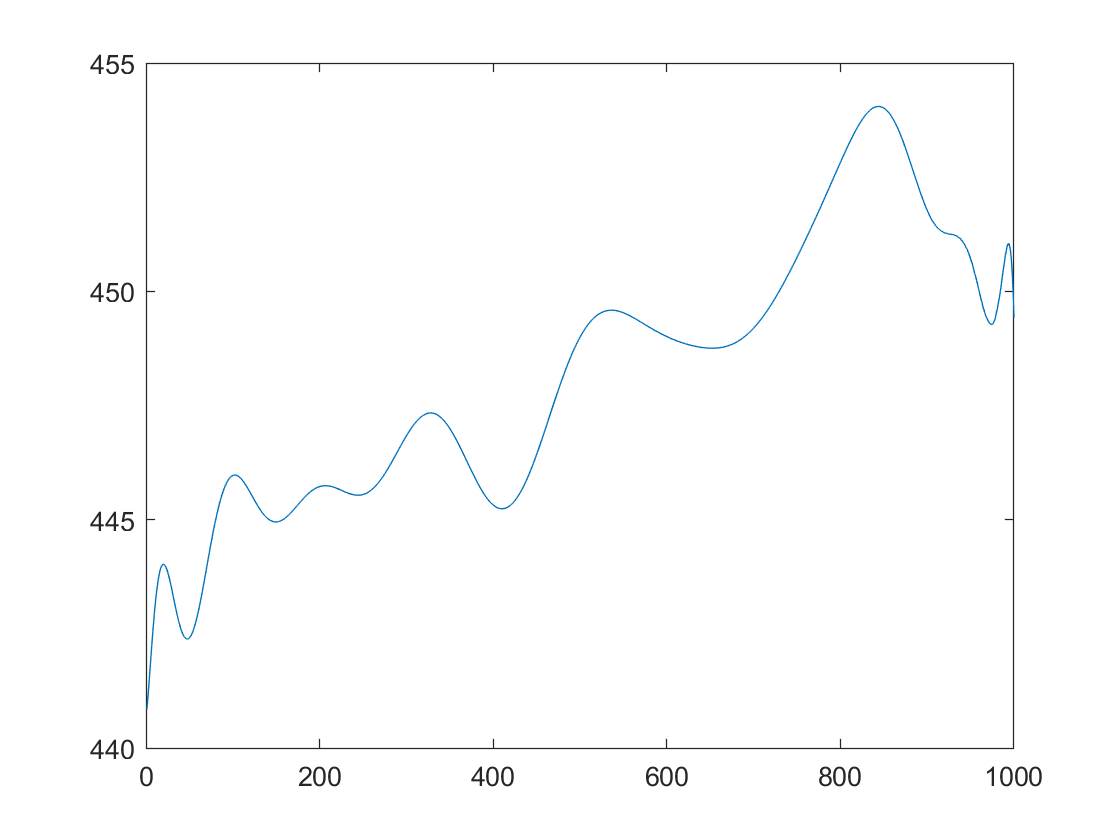

smoothed_data_of_6th_min=polyval(p,time_interval); %data smoothened
plot(smoothed_data_of_6th_min)

title("Polyfitted graph of 6th min")

%Finding number of peaks
no_of_peaks_in_6th_min=findpeaks(smoothed_data_of_6th_min);

%Finding number of peaks
no_of_breathes_in_6th_min = length(no_of_peaks_in_6th_min) % using peak finder function for breaths

no_of_breathes_in_6th_min = 13

#### 6th minute Distance

distance_6th_min = mean(six_recovered);
disp("Person is " + distance_6th_min + " mm away from sensor.")

Person is 448.1308 mm away from sensor.


#### 9th minute Number of Breathes

disp("In 9th minute person is present")

In 9th minute person is present


%Finding number of peaks
no_of_peaks_in_9th_min=findpeaks(nine_recovered);

%Finding number of peaks
no_of_breathes_in_9th_min = length(no_of_peaks_in_9th_min) % using peak finder function for breaths

no_of_breathes_in_9th_min = 12

#### 9th minute Distance

distance_9th_min = mean(nine_recovered);
disp("Person is " + distance_9th_min + " mm away from sensor.")

Person is 440.7076 mm away from sensor.


## Object Present

#### 8th minute Mean Distance

disp("In 8th minute an object is present")

In 8th minute an object is present


distance_8th_min = mean(eight_recovered);
disp("Object is at a distance of " + distance_8th_min + " mm away from sensor.")

Object is at a distance of 150.4376 mm away from sensor.
